## ARI HW02 - Řiditelnost

## Jméno Studenta: Pavel Pernička

Pro zkoumání odvrácené strany měsíce by se hodilo umístit komunikační družici na dráhu zdánlivě obíhajícítranslunární Lagrangeův bod L2 soustavy 3 těles Země-Měsíc-satelit. Tato dráha nazývaná "Halo orbita" jezobrazena na obrázku. Výhodou by bylo, že družice by byla neustále ve spojení jak se Zemí, tak se stanicemina odvrácené straně Měsíce. Uvažme příklad řízení polohy družice v okolí této oběžné dráhy.

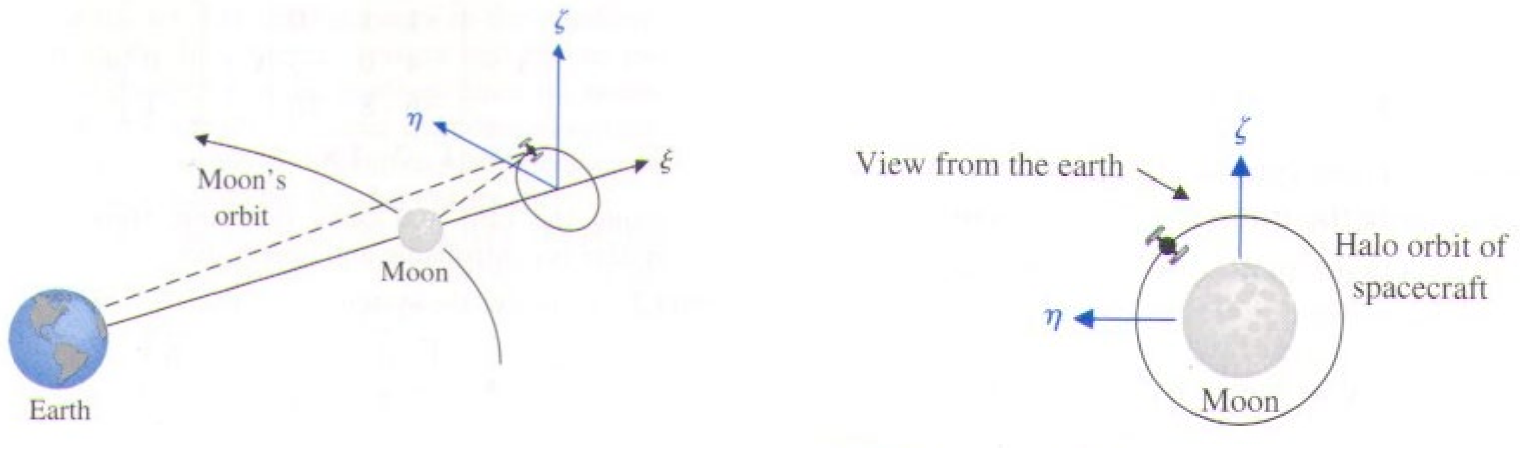

Linearizovaný a normalizovaný model pohybu satelitu okolo translunárního Lagrangeova bodu L2 je(Bishop-Dorf 2005, s. 720) je


$$\dot{x} = 
\pmatrix{0 & 0& 0& 1 & 0 & 0 \cr
0 & 0& 0& 0 & 1 & 0 \cr
0 & 0& 0& 0 & 0 & 1 \cr
7.3809 & 0& 0& 0 & 2 & 0 \cr
0 & -2.1904& 0& -2 & 0 & 0 \cr
0 & 0& -3.1904& 0 & 0 & 0 
}x + 
\pmatrix{0\cr0\cr0\cr1\cr0\cr0\cr
}u_1+
\pmatrix{0\cr0\cr0\cr0\cr1\cr0\cr
}u_2+
\pmatrix{0\cr0\cr0\cr0\cr0\cr1\cr
}u_3$$


kde stavový vektor tvoří polohy a rychlosti a vstupy $u_i, i = 1,2,3$ jsou zrychlení vyvolaná tryskovými motoryve směrech po řadě $\xi, \zeta, \eta$ dle obrázku.

#### Úkol 1 

Je tento lineární systém stabilní? Pokud ano, pak je i translunární ekvilibrium stabilní polohou.

%% stabilita
% Zjistím vlastní čísla té matice
A = [ 0       0       0       1      0      0;
      0       0       0       0      1      0;
      0       0       0       0      0      1;
      7.3809  0       0       0      2      0;
      0      -2.1904  0      -2      0      0;
      0       0      -3.1904  0      0      0 ];

lambda = eig(A)
% Musí splňovat Re lambda < 0 - to nesplňují => systém je nestabilní

#### Úkol 2

Pokud není, zjistěte kterým vstupem (a tedy kterým tryskovým motorem) je systém řiditelný.

Rada: Protože jsme dosud měli pouze systémy s jedním vstupem, uvažte každý případ jednotlivě.

%% Pomocí kterého vstupu je systém řiditelný?
% Pro každý vstup b1, b2, b3 sestavíme matici řiditelnosti C ([b, Ab, A^2b ... A^{n-1}b], resp. funkce ctrb(A,bn);) a podíváme se
% na její rank. Pokud By byl systém některým vstupem řiditelný, měla by
% rank(C) = řád systému = 6.
A = [ 0       0       0       1      0      0;
      0       0       0       0      1      0;
      0       0       0       0      0      1;
      7.3809  0       0       0      2      0;
      0      -2.1904  0      -2      0      0;
      0       0      -3.1904  0      0      0 ];

b1 = [0;0;0;1;0;0];
b2 = [0;0;0;0;1;0];
b3 = [0;0;0;0;0;1];

Co1 = ctrb(A,b1);
Co2 = ctrb(A,b2);
Co3 = ctrb(A,b3);

r1 = rank(Co1) %4
r2 = rank(Co2) %4
r3 = rank(Co3) %2

% Z toho plyne, že systém není plně řiditelný pomocí žádného z motorů (pokud je bereme samostatně)

#### Úkol 3

Vypočtěte postupně pro každý vstup (tryskový motor) přenos na stav. Poznáte z nich totéž, co jste zjistili v bodu 2?

%% Přenosy u každého motoru jednotlivě
% Přenos z matice A a vstupů b1, b2, b3 spočítám jako
% H(s) = (sIdentita-A)^{-1} * b_n.

A = [ 0       0       0       1      0      0;

ans =
 
  s - 1
 
Continuous-time transfer function.



      0       0       0       0      1      0;
      0       0       0       0      0      1;
      7.3809  0       0       0      2      0;
      0      -2.1904  0      -2      0      0;
      0       0      -3.1904  0      0      0 ];

b1 = [0;0;0;1;0;0];
b2 = [0;0;0;0;1;0];
b3 = [0;0;0;0;0;1];

syms s
I = eye(size(A,1));

H1 = simplify((s*I - A)\b1)
H2 = simplify((s*I - A)\b2)
H3 = simplify((s*I - A)\b3)

% v maticích přenosů vidíme nulové řádky, což nám ukazuje na totéž, co
% předchozí bod.

#### Úkol 4

Uvažte nyní celý systém se třemi vstupy a ověřte jeho řiditelnost. Postupujte formálně stejně jako v bodu 2), tj. vypočtěte matici řiditelnosti, kde nyní místo sloupcového vektoru B máme matici vstupních vektorů 6x3, vypočtete její hodnost a zjistěte, zda se rovná řádu systému.

%% Řiditelnost všemi motory zaráz

Invalid expression. Check for missing or extra characters.

A = [ 0       0       0       1      0      0;
      0       0       0       0      1      0;
      0       0       0       0      0      1;
      7.3809  0       0       0      2      0;
      0      -2.1904  0      -2      0      0;
      0       0      -3.1904  0      0      0 ];

b1 = [0;0;0;1;0;0];
b2 = [0;0;0;0;1;0];
b3 = [0;0;0;0;0;1];

B  = [b1 b2 b3];
Co = ctrb(A,B);
rank(Co)

% Zde nám vyjde rank 6, systém je tedy řiditený pomocí všech motorů zaráz

#### Úkol 5

 Vypočtete přenosovou matici ze vstupů na stav pro celkový systém (se třemi vstupy).

%% Přenos se všemi motory zaráz
A = [ 0       0       0       1      0      0;
      0       0       0       0      1      0;
      0       0       0       0      0      1;
      7.3809  0       0       0      2      0;
      0      -2.1904  0      -2      0      0;
      0       0      -3.1904  0      0      0 ];

b1 = [0;0;0;1;0;0];
b2 = [0;0;0;0;1;0];
b3 = [0;0;0;0;0;1];

B  = [b1 b2 b3];

syms s
I = eye(size(A,1));

H1 = simplify((s*I - A)\B)

% Tady už nejsou nulové řádky
%[  -(10000*(625*s^2 + 1369))/(- 6250000*s^4 + 7440625*s^2 + 101044521),                -(12500000*s)/(- 6250000*s^4 + 7440625*s^2 + 101044521),                        0]
%[               (12500000*s)/(- 6250000*s^4 + 7440625*s^2 + 101044521),   -(625*(10000*s^2 - 73809))/(- 6250000*s^4 + 7440625*s^2 + 101044521),                        0]
%[                                                                    0,                                                                      0,     625/(625*s^2 + 1994)]
%[-(10000*s*(625*s^2 + 1369))/(- 6250000*s^4 + 7440625*s^2 + 101044521),              -(12500000*s^2)/(- 6250000*s^4 + 7440625*s^2 + 101044521),                        0]
%[             (12500000*s^2)/(- 6250000*s^4 + 7440625*s^2 + 101044521), -(625*s*(10000*s^2 - 73809))/(- 6250000*s^4 + 7440625*s^2 + 101044521),                        0]
%[                                                                    0,                                                                      0, (625*s)/(625*s^2 + 1994)]